# INTERPOLACIÓN DE LAGRANGE BASE- Li

Datos iniciales según si me dan la funcion o los puntos

% f = @(x) ; %función conocida o a comparar con la interpolación
xi = [0 1 3 ];
%fi = [3 2.25 2 ];
 fi =@(x) (3 + x).*cos(pi*x/4).^2; % si función conocida

x=2

x = 2

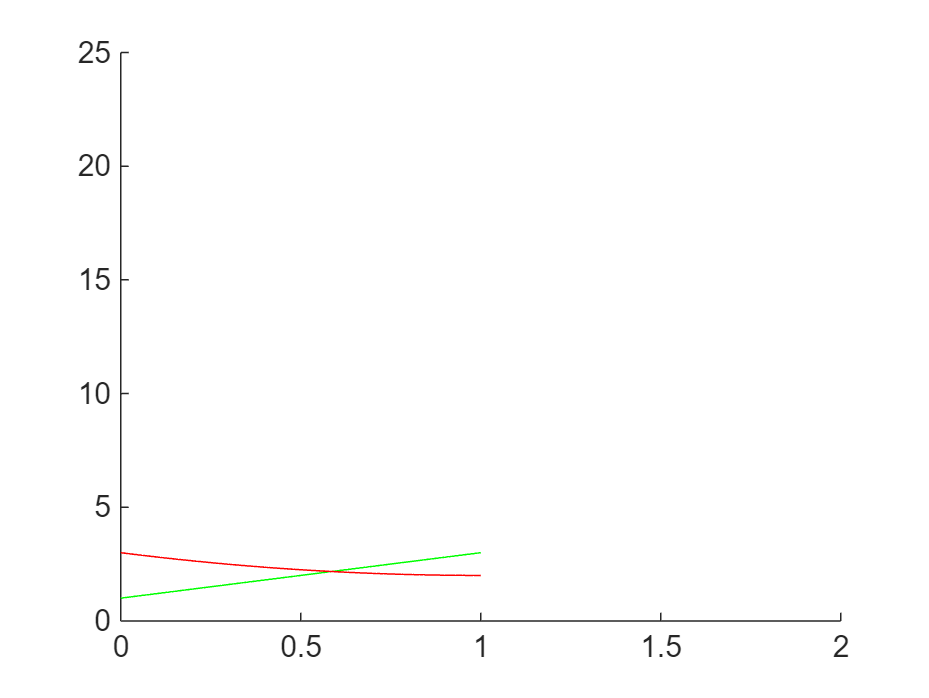

%x = 0:0.01:1; %puntos en los que obtener evaluado el pol interpolador
p = 0*x; 

for i=1:length(xi) 
    li=0*x+1;

    for j=1:length(xi)
        if i ~= j
         li = li.*(x-xi(j))/(xi(i)-xi(j));
        end
    end

    p = p + fi(i)*li; 

end

hold on 
%plot(x,f(x),'b') %representar función 
plot(x,p,'r')
hold off

%scatter(xi, fi, 'r')
